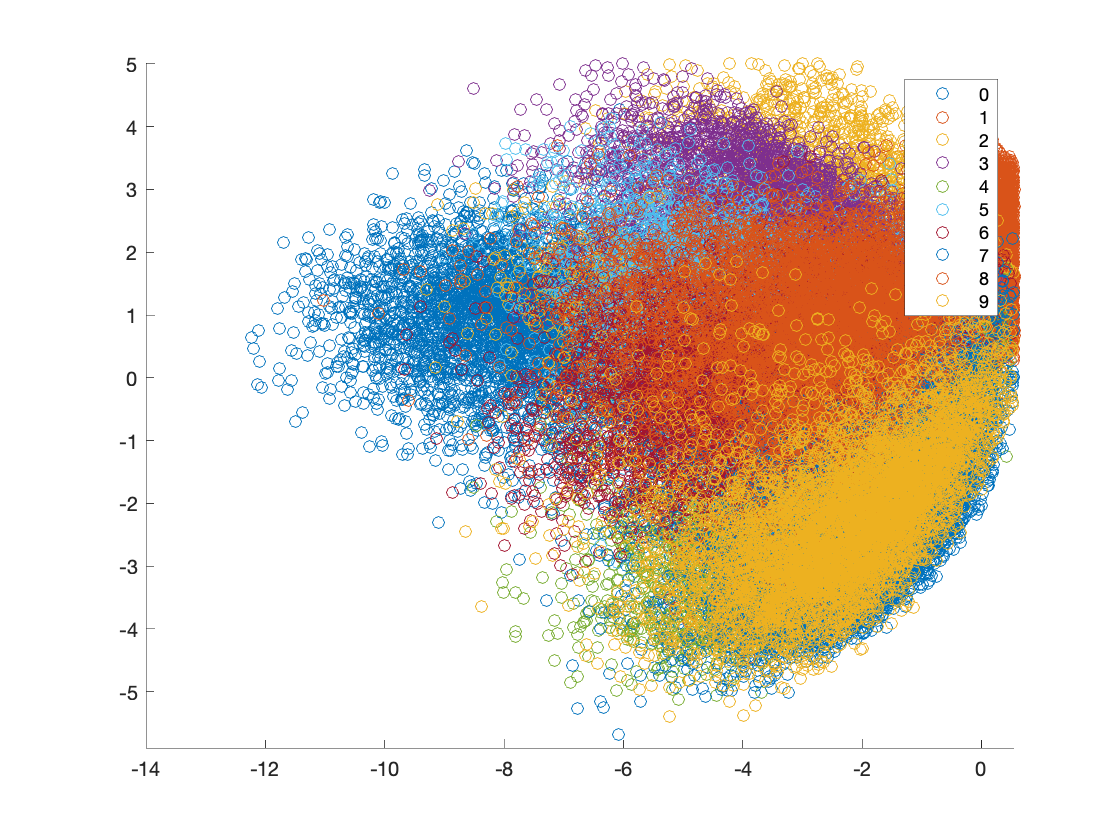

% P5 COMP4702
%
% Author: Brian Chen

% Q2(a)

load mnist_train.mat;

% We implement our own pca function below
[Y,lambda] = pca(train_X, 2);

Ce = {};

figure; hold on;
for i = 1:10
    Ce{i} = Y(train_labels==i, :);
    scatter ( Ce{i} (:, 1) , Ce{i} (:, 2));
end
legend('0', '1', '2', '3', '4', '5', '6', '7', '8', '9');

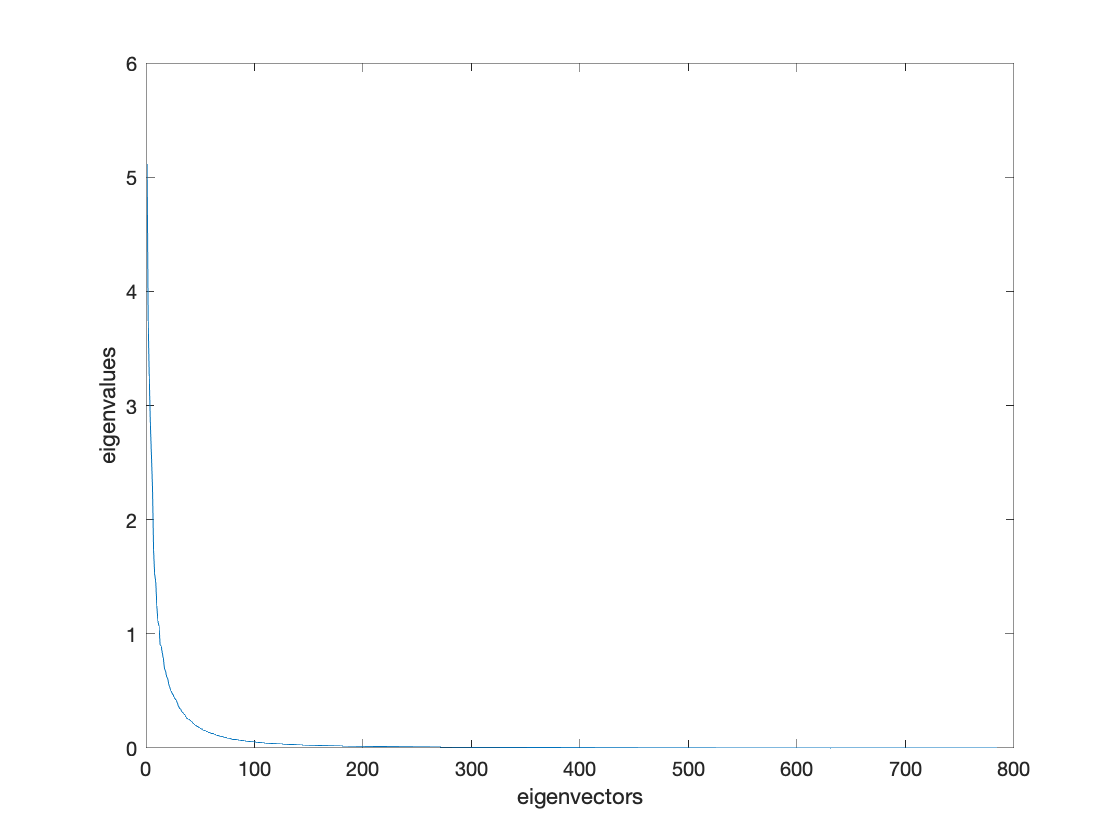

% Q2(b)
figure;
plot(lambda);
ylim([0, 6]);
xlabel('eigenvectors');
ylabel('eigenvalues');

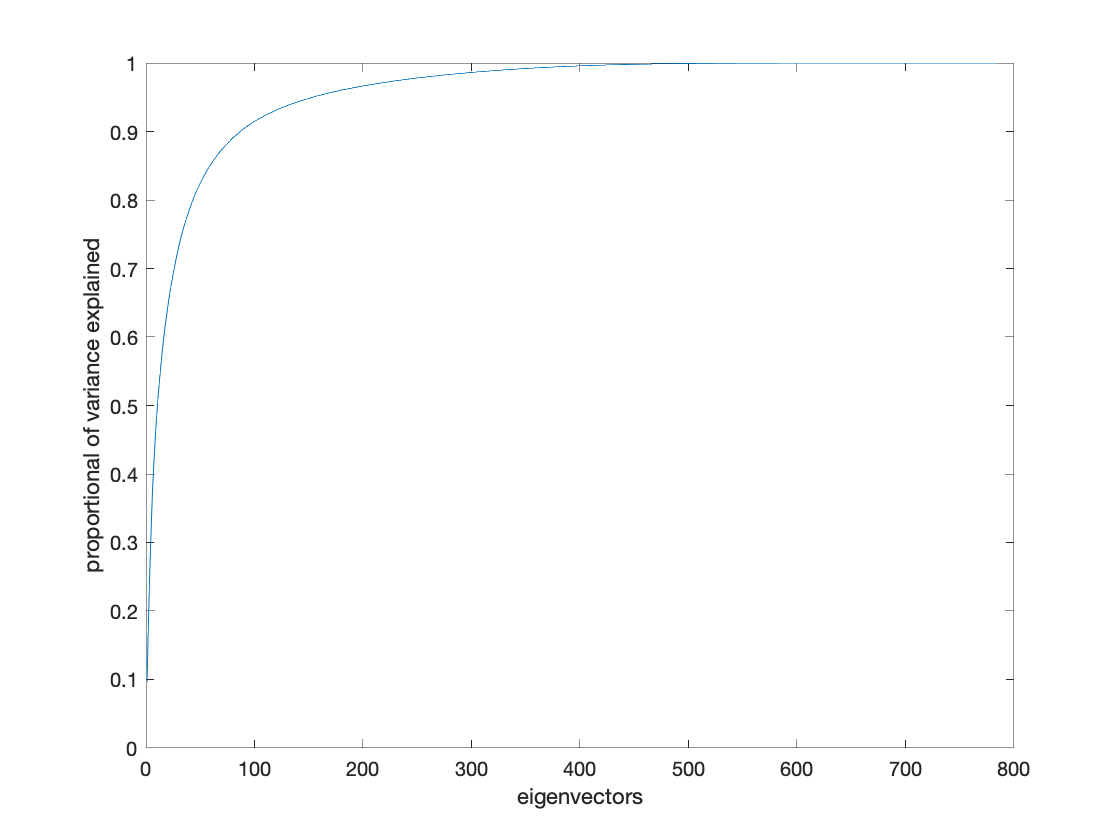

% Q2(c)
figure;
varexplained = cumsum(lambda)./sum(lambda);
plot(varexplained);
xlabel('eigenvectors');
ylabel('proportional of variance explained');


disp(['Proportion of var explained by first 2 principle components: ' ...
    num2str(varexplained(2))]);

Proportion of var explained by first 2 principle components: 0.16801


% Q3 - Exercise

Preprocessing data using PCA...
Computed P-values 500 of 6000 datapoints...
Computed P-values 1000 of 6000 datapoints...
Computed P-values 1500 of 6000 datapoints...
Computed P-values 2000 of 6000 datapoints...
Computed P-values 2500 of 6000 datapoints...
Computed P-values 3000 of 6000 datapoints...
Computed P-values 3500 of 6000 datapoints...
Computed P-values 4000 of 6000 datapoints...
Computed P-values 4500 of 6000 datapoints...
Computed P-values 5000 of 6000 datapoints...
Computed P-values 5500 of 6000 datapoints...
Computed P-values 6000 of 6000 datapoints...
Mean value of sigma: 1.8217
Minimum value of sigma: 0.68169
Maximum value of sigma: 3.133
Iteration 10: error is 57.3531


Iteration 20: error is 57.3272


Iteration 30: error is 52.7312


Iteration 40: error is 51.6631


Iteration 50: error is 51.0345


Iteration 60: error is 50.6164


Iteration 70: error is 50.3226


Iteration 80: error is 50.1156


Iteration 90: error is 49.9572


Iteration 100: error is 3.2764


Iteration 110: error is 2.97


Iteration 120: error is 2.7209


Iteration 130: error is 2.5275


Iteration 140: error is 2.3765


Iteration 150: error is 2.2575


Iteration 160: error is 2.1668


Iteration 170: error is 2.0998


Iteration 180: error is 2.0435


Iteration 190: error is 1.9946


Iteration 200: error is 1.9537


Iteration 210: error is 1.9181


Iteration 220: error is 1.887


Iteration 230: error is 1.8595


Iteration 240: error is 1.835


Iteration 250: error is 1.813


Iteration 260: error is 1.7769


Iteration 270: error is 1.7347


Iteration 280: error is 1.6981


Iteration 290: error is 1.6681


Iteration 300: error is 1.6432


Iteration 310: error is 1.6216


Iteration 320: error is 1.6026


Iteration 330: error is 1.5857


Iteration 340: error is 1.5709


Iteration 350: error is 1.5576


Iteration 360: error is 1.5455


Iteration 370: error is 1.5346


Iteration 380: error is 1.5246


Iteration 390: error is 1.5154


Iteration 400: error is 1.5069


Iteration 410: error is 1.4991


Iteration 420: error is 1.4918


Iteration 430: error is 1.4851


Iteration 440: error is 1.4788


Iteration 450: error is 1.4728


Iteration 460: error is 1.4672


Iteration 470: error is 1.462


Iteration 480: error is 1.4571


Iteration 490: error is 1.4524


Iteration 500: error is 1.448


Iteration 510: error is 1.4439


Iteration 520: error is 1.4399


Iteration 530: error is 1.4362


Iteration 540: error is 1.4326


Iteration 550: error is 1.4292


Iteration 560: error is 1.4259


Iteration 570: error is 1.4228


Iteration 580: error is 1.4198


Iteration 590: error is 1.417


Iteration 600: error is 1.4142


Iteration 610: error is 1.4116


Iteration 620: error is 1.4091


Iteration 630: error is 1.4067


Iteration 640: error is 1.4043


Iteration 650: error is 1.4021


Iteration 660: error is 1.3999


Iteration 670: error is 1.3978


Iteration 680: error is 1.3958


Iteration 690: error is 1.3938


Iteration 700: error is 1.3919


Iteration 710: error is 1.3901


Iteration 720: error is 1.3883


Iteration 730: error is 1.3866


Iteration 740: error is 1.385


Iteration 750: error is 1.3834


Iteration 760: error is 1.3819


Iteration 770: error is 1.3804


Iteration 780: error is 1.379


Iteration 790: error is 1.3776


Iteration 800: error is 1.3762


Iteration 810: error is 1.3748


Iteration 820: error is 1.3736


Iteration 830: error is 1.3723


Iteration 840: error is 1.3711


Iteration 850: error is 1.3699


Iteration 860: error is 1.3688


Iteration 870: error is 1.3677


Iteration 880: error is 1.3666


Iteration 890: error is 1.3655


Iteration 900: error is 1.3645


Iteration 910: error is 1.3635


Iteration 920: error is 1.3625


Iteration 930: error is 1.3616


Iteration 940: error is 1.3606


Iteration 950: error is 1.3597


Iteration 960: error is 1.3589


Iteration 970: error is 1.358


Iteration 980: error is 1.3571


Iteration 990: error is 1.3563


Iteration 1000: error is 1.3555


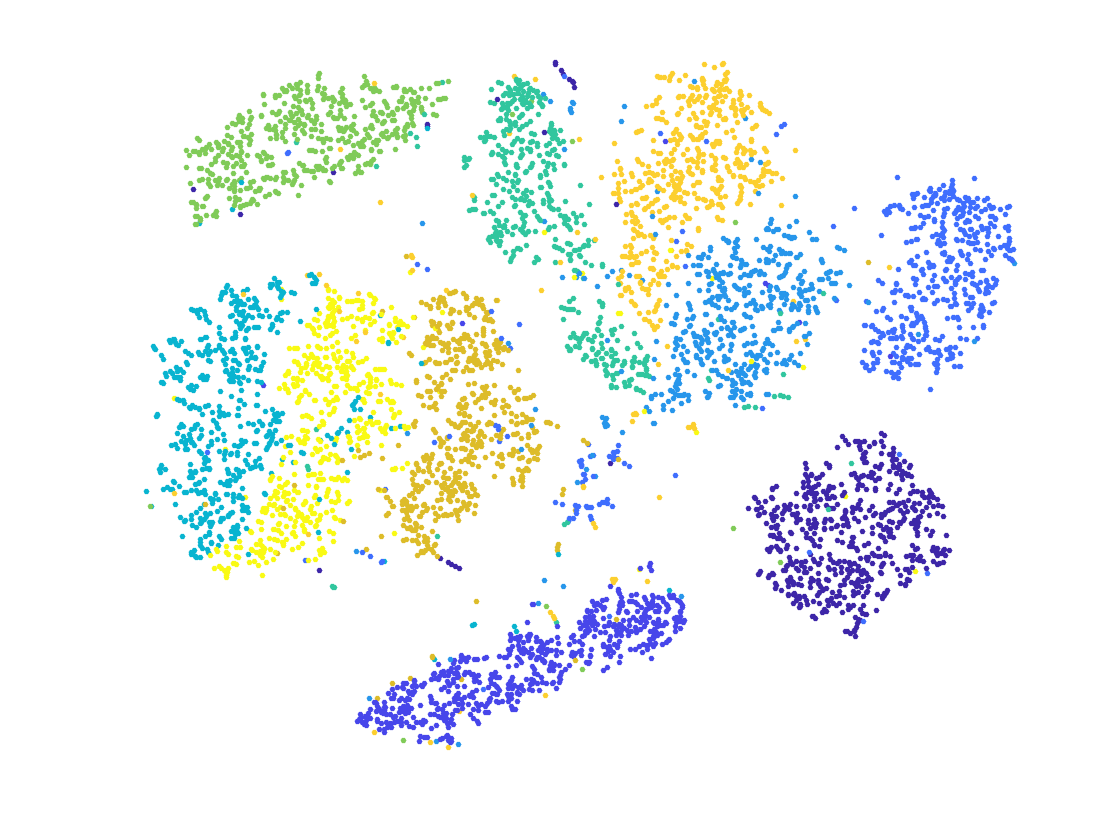

% PART II
% Q1
% student t-distribution

load('mnist_train.mat');
idx = unidrnd(60000, 6000, 1);
x = train_X(idx, :);
labels = train_labels(idx);
tsne(x, labels, 2, 30, 30);


% Q2 - Exercise

% Q3 - Exercise

% Q4 - Early exaggeration

% Q5 - Takes a LOT of time. See Q5.m for results

% Q6 - Lower cost ALWAYS produces a better visualisation?

% 
%
%
%
%

function [Y,eVal] = pca(X, dim)
    C = cov(X); % covariance of X
    [eVect, eVal] = eig(C); % eigenvectors (V) and eigenvalues (D)
    eVal = diag(eVal); % diagonal matrix of eigenvalues
    [eVal, I] = sort(eVal, 'descend'); % sort eigenvalues descending
    eVect = eVect(:, I);
    Y = X * eVect(:, 1:dim);
end